# **Recuperatorio Examen Parcial 1: Control y Sistemas 2025**

## **Requerimientos de Ingeniería**

Se recuperan las señales de dos sensores distintos $x_c(t)$ y $x_r(t)$. La primera es una onda senoidal y la segunda una onda rectangular. Ambas señales han sido tratadas con un filtro antialiasing pero acarrean unas perturbaciones particulares que se quieren remover. Debemos realizar el tratamiento correspondiente con el método oversampling para lograr ingresarlas a un sistema de cómputo discreto (procesador digital o  DSP) donde se realizarán operaciones con la información que traen. 

Para ello es necesario asegurarse de remover el ruido que tienen diseñando filtros para cada una de las señales y hacerlo logrando mantener la forma de la onda, evitar el desfasaje y tener una buena relación ruido-señal. 

Buscamos que el procesador pueda realizar tratamiento de las señales confiando que la que que proveemos tienen la información y forma más cercana a la ideal.   

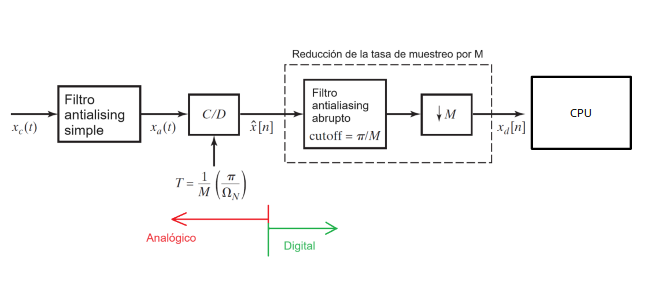

### **Antes de iniciar los cálculos y el diseño**

Describa lo que interpreta del requerimiento de la aplicación. Explique cómo procederá para resolverlo reducido a tres simples pasos de manera descriptiva y simple. Pensando en que deberá comunicarlo a otras personas con las que trabaja.   

## Descripción de las señales

Tenemos dos señales distintas $x_c(t)$ y $x_r(t)$. **Ambas señales son interferidas por ruidos distintos.**

La frecuencia de la señal senoidal $x_c(t)$** es de 7Hz**. La frecuencia de la señal rectangular $x_r(t)$** es de 1Hz**

El filtro antialiasing analógico simple que se les **ha aplicado tiene una atenuación de -3 dB en 150 Hz y -60 dB en 250 Hz** (no es necesario diseñar este filtro). 

La señal senoidal acarrea una componente de **ruido senoidal del 50Hz**. En cambio la **señal rectangular es atacada por un ruido gaussiano** tal que la relación señal-ruido entre la señal rectangular y el ruido es de 2dB.

clc
clear
close all
%% Frecuencia de signals
frequency_xc = 7;        % [Hz] frequency of signal 1
frequency_xr = 1;       % [Hz] frequency of signal 2
frequency_noise = 50;      % [Hz]
% Definir SNR deseado ruido onda rectangular (en dB)
SNR_dB = 2;

## Muestreo y señales

### Determinación de la mínima frecuencia de muestreo

Necesitamos que la etapa de muestreo evite errores por aliasing y que podamos recuperar la información original que tiene la señal.

Que frecuencia de muestreo considera conveniente. Justifique. 

### Declaración de parámetros de muestreo

#### Parámetros de las señal  

% COLOQUE LA FRECUENCIA DE MUESTREO AQUÍ REEMPLAZANDO EL VALOR 1 
fs = 300;    % [Hz] how often the signal is sampled

#### Rango de tiempo y vector de tiempo

start_time = 0;         % [s] beginning of the time window
end_time = 1;         % [s] end of the time window

t = start_time : 1/fs : end_time;  % [s] time points at which the signal is sampled

## Construcción de las señales y ruidos

#### Señal 1, señal 2 y ruidos

Construya usando su vector de tiempo las señales senoidales y rectangular. 

Construya los ruidos y apliquelos a las señales. 


% 2π * frequency [rad/s] * time [s] → [rad] → sin(...) → unitless amplitude
signal_xc = sin(2 * pi * frequency_xc * t);         % [1] sine wave values (unitless amplitude)
signal_xr = square(2 * pi * frequency_xr * t);

% ruido signal sin xc
noise_xc = sin(2 * pi * frequency_noise * t); % NO ALTERAR LA AMPLITUD DEL RUIDO

% ruido signal rectangular xr
% AGREGE AQUÍ EL RUIDO A LA SEÑAL RECTANGULAR
SNR_dB = 2;
signal_noise_xc = signal_xc + noise_xc;        % [1] signal with additional noise
signal_noise_xr = awgn(signal_xr, SNR_dB, 'measured');	    % [1] signal with additional noise  <


#### Plot de señales en el dominio del tiempo

Realice un plot de la señales sin la perturbación, el ruido y la señal con la perturbación agregada. 

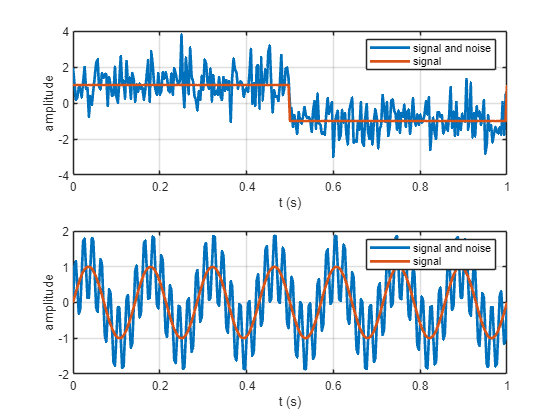

figure
hold on
subplot(2,1,1)
plot(t, [signal_noise_xr; signal_xr], 'linewidth', 2)
xlabel('t (s)')
ylabel('amplitude')
legend('signal and noise', 'signal')
grid on
subplot(2,1,2)
plot(t, [signal_noise_xc; signal_xc], 'linewidth', 2)
xlabel('t (s)')
ylabel('amplitude')
legend('signal and noise', 'signal')
grid on

#### Plot de señales en el dominio de la frecuencia

El siguiente código realiza un plot de la señales en el dominio de la frecuencia mostrando sus componentes. Escriba sus conclusiones y respuestas a las preguntas en esta sección.

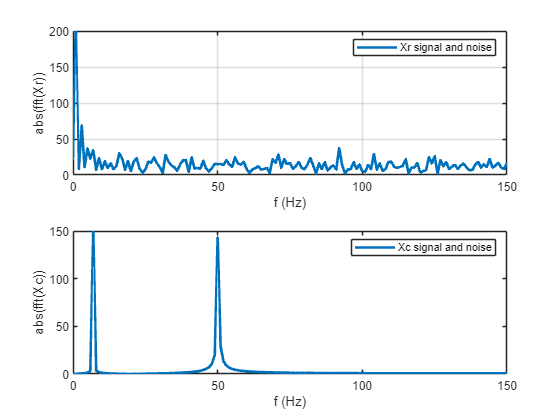

Xr = abs(fft(signal_noise_xr));
Xc = abs(fft(signal_noise_xc));
figure
subplot(2,1,1)
plot(linspace(0, fs/2, round(length(Xr)/2)), Xr(1:round(length(Xr)/2)), 'linewidth', 2);
xlabel('f (Hz)')
ylabel('abs(fft(Xr))')
legend('Xr signal and noise')
grid on
subplot(2,1,2)
plot(linspace(0, fs/2, round(length(Xc)/2)), Xc(1:round(length(Xc)/2)), 'linewidth', 2);
xlabel('f (Hz)')
ylabel('abs(fft(Xc))')
legend('Xc signal and noise')

### Conclusiones

***La señal tiene más información representada en el dominio del tiempo y o de la frecuencia?***

***Esto puede influir en la elección del filtro?***

## Filtrado y Decimación

### Las características del decimador y del filtro digital que debe implementar

Deberá elegir entre alguna de las implementaciones de filtros posibles. Fundamente porque realizó dicha elección.

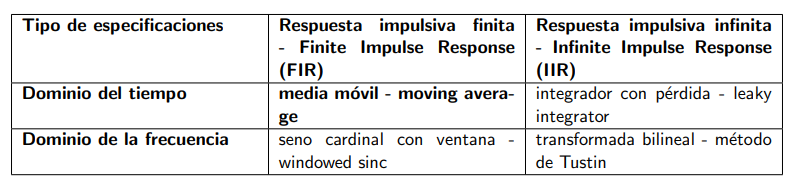

### Diseño del filtro FIR onda senoidal


%COLOQUE EL CÓDIGO DE SU FILTRO AQUÍ
fcero = 50;

N = round(fs/fcero)

N = 6

Hd=filtrohamming;
b = Hd.Numerator;
a = 1;
filtered_signal_xc = filtfilt(b, a, signal_noise_xc);


#### Polos, ceros y diagrama de bode

Realice un plot para ver ceros, polos y el diagrama de bode del filtro

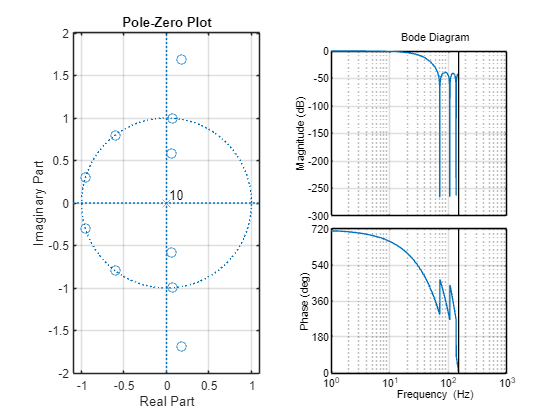

figure
opts = bodeoptions;
opts.FreqUnits = 'Hz';
subplot(1,2,1)
zplane(b,a)
grid on
subplot(1,2,2)
bode(filt(b, a, 1/fs),opts)
grid on

#### Decimación onda senoidal: selección de la nueva frecuencia de muestreo. 

Realice una decimación de la onda filtrada, justifique la nueva frecuencia de muestreo. 

%COLOQUE EL VALOR DE LA FRECUENCIA DE SUBMUESTREO

fs_new =30 %fs/(2*frequency_xr) % Hz

fs_new = 30


subsampled_filt_signal_xc = filtered_signal_xc(1:round(fs/fs_new):end);
subsampled_t = t(1:round(fs/fs_new):end);

### Análisis en frecuencia y tiempo onda senoidal

Utilice los siguientes plots en el dominio de la frecuencia y el tiempo de la señal con ruido y la señal filtrada para comprobar los resultados de su filtro. 

#### Código análisis en frecuencia

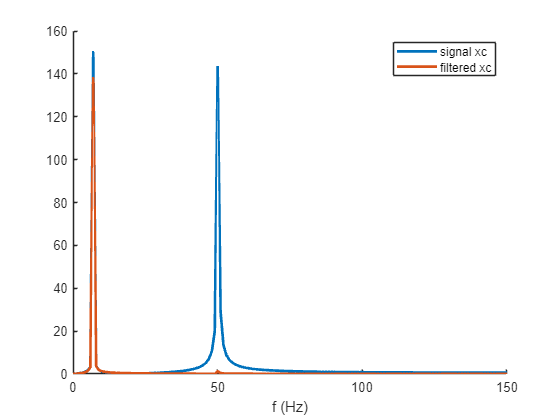


X = abs(fft(signal_noise_xc));
X_filt = abs(fft(filtered_signal_xc));
figure
hold on
plot(linspace(0, fs/2, round(length(X)/2)), X(1:round(length(X)/2)), 'linewidth', 2);
plot(linspace(0, fs/2, round(length(X_filt)/2)), X_filt(1:round(length(X_filt)/2)), 'linewidth', 2);
legend('signal xc', 'filtered xc')
xlabel('f (Hz)')

#### Código análisis en tiempo

Grafique la señal original, la que tiene ruido y la filtrada para ver una compararción. La señal filtrada tiene mucho desfasaje? en tiempo o en forma? Explique

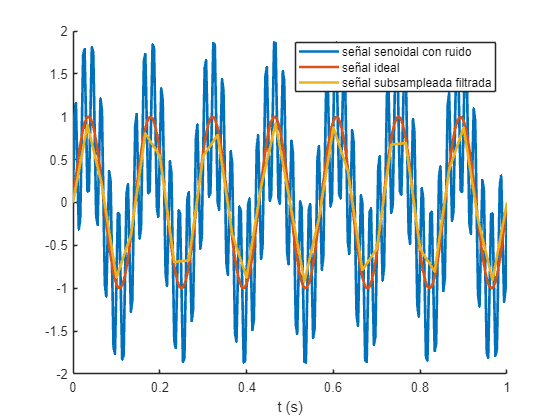

figure
hold on
plot(t, [signal_noise_xc; signal_xc], 'linewidth', 2)
plot(subsampled_t, subsampled_filt_signal_xc, 'linewidth', 2)
xlabel('t (s)')
legend('señal senoidal con ruido', 'señal ideal', 'señal subsampleada filtrada')

#### Cálculo de SNR para score del filtro de onda senoidal

subsampled_signal_xc = signal_xc(1:round(fs/fs_new):end);
SNR_xc = 20*log10(rms(subsampled_signal_xc)/rms(subsampled_filt_signal_xc - subsampled_signal_xc))

SNR_xc = 21.9291

if SNR_xc < 16
    disp(100*SNR_xc/16)
else
    disp(100)
end

   100



### Resultados onda senoidal

*** ¿La señal filtrada tiene mucho desfasaje? ¿distorsiona la forma? Explique sus resultados***

### Diseño del filtro FIR onda cuadrada


% COLOQUE EL CÓDIGO DE SU FILTRO AQUÍ
N = 15;
b_xr = (1/N)*ones(1,N);        % Coeficientes del filtro MA
a_xr = 1;
filtered_signal_xr = filter(b_xr, a_xr, signal_noise_xr);


#### Polos, ceros y diagrama de bode

Realice un plot para ver ceros, polos y el diagrama de bode del filtro

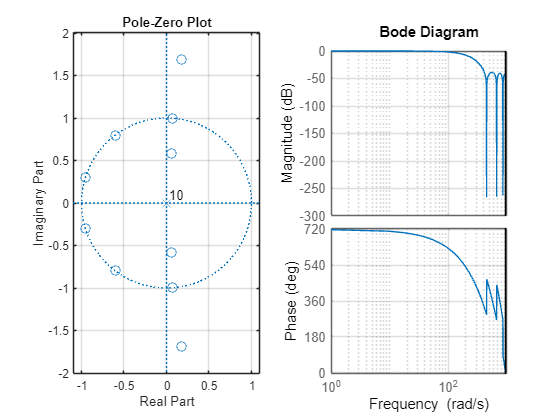

figure
subplot(1,2,1)
zplane(b,a)
grid on
subplot(1,2,2)
bode(filt(b, a, 1/fs))
grid on

#### Decimación onda cuadrada

Realizamos la decimación usando la nueva frecuencia de muestreo elegida previamente. 

subsampled_filt_signal_xr = filtered_signal_xr(1:round(fs/fs_new):end);

### Análisis en frecuencia y tiempo onda cuadrada

Utilice los siguientes plots en el dominio de la frecuencia y el tiempo de la señal con ruido y la señal filtrada para comprobar los resultados de su filtro. 

#### Código análisis en frecuencia

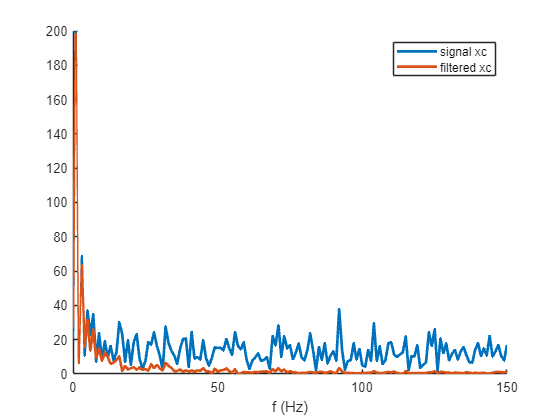

X = abs(fft(signal_noise_xr));
X_filt = abs(fft(filtered_signal_xr));
figure
hold on
plot(linspace(0, fs/2, round(length(X)/2)), X(1:round(length(X)/2)), 'linewidth', 2);
plot(linspace(0, fs/2, round(length(X_filt)/2)), X_filt(1:round(length(X_filt)/2)), 'linewidth', 2);
legend('signal xc', 'filtered xc')
xlabel('f (Hz)')

#### Código análisis en tiempo

Grafique la señal original, la que tiene ruido y la filtrada para ver una compararción. 

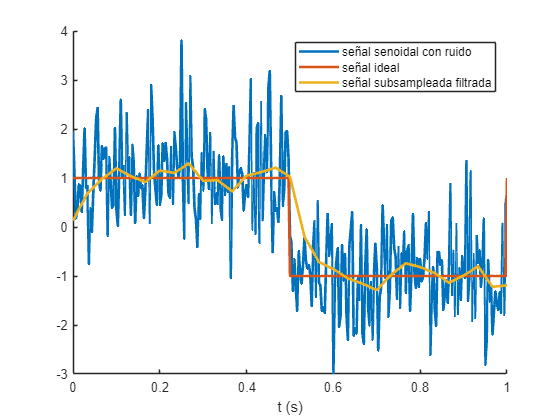

figure
hold on
plot(t, [signal_noise_xr; signal_xr], 'linewidth', 2)
plot(subsampled_t, subsampled_filt_signal_xr, 'linewidth', 2)
xlabel('t (s)')
legend('señal senoidal con ruido', 'señal ideal', 'señal subsampleada filtrada')

###  Cálculo de SNR para score del filtro de onda cuadrada

subsampled_signal_xr = signal_xr(1:round(fs/fs_new):end);
SNR_xr = 20*log10(rms(subsampled_signal_xr)/rms(subsampled_filt_signal_xr - subsampled_signal_xr))

SNR_xr = 4.4493

if SNR_xr < 8.1
    disp(100*SNR_xr/8.1)
else
    disp(100)
end

   54.9291



### Resultados onda senoidal

*** ¿La señal filtrada tiene mucho desfasaje? ¿distorsiona la forma? Explique sus resultados***

## ADC

***¿Cuántos bits tendría que tener el ADC de cada canal en función del ruido observado suponiendo 1 bit de guarda para el ruido?***

## Análisis de aritmética punto fijo o flotante 

### **Sugiera una representación en punto fijo que sea óptima para almacenar la señal senoidal, sin la presencia del ruido.**

### ***Teniendo toda la información reunida hasta ahora. Que representación usaría para el diseño del filtro para optimizar recursos manteniendo la precisión necesaria. Elija una opción. ***